% image
imageFolder = 'imagemitsuba/cu_0.025/';
imageFiles = dir(fullfile(imageFolder, '*.mat')); % フォーマットに応じて変更
imgcnt = 3;
matFilePath = fullfile(imageFolder, imageFiles(imgcnt).name);
data = load(matFilePath);
%color space
cform1 = makecform('xyl2xyz')

cform1 = フィールドをもつ struct :
            c_func: @xyl2xyz
     ColorSpace_in: 'xyl'
    ColorSpace_out: 'xyz'
          encoding: 'double'
             cdata: [1×1 struct]


cform2 = makecform('xyz2xyl')

cform2 = フィールドをもつ struct :
            c_func: @xyz2xyl
     ColorSpace_in: 'xyz'
    ColorSpace_out: 'xyl'
          encoding: 'double'
             cdata: [1×1 struct]


%callibration
callibration_Path = 'callibration/'

callibration_Path = 'callibration/'

spectrum_data = readmatrix(fullfile(callibration_Path,'spectr.csv'));
c = tnt.RgbConverter(spectrum_data);
gamma_converter =load(fullfile(callibration_Path,"gamma_converter.mat")).gamma_converter;

%---Input xyY---
%{
xyYImgin = data.image_np_xyY; 
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
lum_av = mean(xyYImgin(:))
disp(lum_av)

xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input xyY---xyYImgin(:,:,3)
%---Input XYZ---
%{
xyzImgin = data.image_np_XYZ_900;
xyYImgin = applycform(xyzImgin,cform2);
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input XYZ---
%---Input XYZ 2---

xyzImgin = double(data.image_XYZ);
xyYImgin = applycform(xyzImgin,cform2);
Ychan = xyYImgin(:,:,3)

Ychan =     1.1971    1.1860    1.1743    1.1589    1.1436    1.1313    1.1201    1.1055    1.0948    1.0808    1.0630    1.0502    1.0398    1.0272    1.0152    1.0055    0.9968    0.9848    0.9692    0.9597    0.9510    0.9409    0.9300    0.9207    0.9102    0.9032    0.8954    0.8877    0.8805    0.8706    0.8635    0.8562    0.8488    0.8438    0.8375    0.8282    0.8225    0.8172    0.8123    0.8100    0.8075    0.8041    0.8017    0.7972    0.7946    0.7921    0.7842    0.7792    0.7770    0.7743
    1.1368    1.1293    1.1217    1.1105    1.0980    1.0872    1.0769    1.0632    1.0520    1.0399    1.0260    1.0151    1.0076    0.9962    0.9869    0.9777    0.9673    0.9572    0.9439    0.9341    0.9252    0.9159    0.9063    0.8963    0.8895    0.8809    0.8739    0.8677    0.8606    0.8519    0.8461    0.8387    0.8316    0.8288    0.8247    0.8149    0.8096    0.8052    0.8035    0.7994    0.7972    0.7966    0.7938    0.7887    0.7848    0.7830    0.7761    0.7715    0.7690 

LDR_Y = Reinhard(Ychan,1.0)*30;
%LDR_Y = ReinhardTMO(Ychan,1,1,'global',8,1.19)*100;
lum_av = mean(Ychan(:))

lum_av = 0.9966

disp(lum_av)

    0.9966




xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);


xyzImgcom = rgb2xyz(digital_rgb);
xyYImgcom = applycform(xyzImgcom,cform1);
Ychan_com = xyYImgcom(:,:,3);
lum_av_com = mean(Ychan_com(:));
disp(lum_av_com);

    0.6711



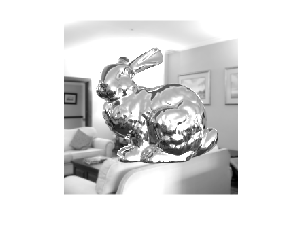

%}
%---Input XYZ 2---
%---Input rgb---
%{
rgbImgin = data.rgb_data;
xyzImgin = rgb2xyz(rgbImgin);
xyYImgin = applycform(xyzImgin,cform2);
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input rgb---

% confirm
xyzImgin = applycform(xyYImgin,cform1);
rgbImgin = xyz2rgb(xyzImgin);
rgbImgout = xyz2rgb(xyzImgout);
imshow(rgbImgin);

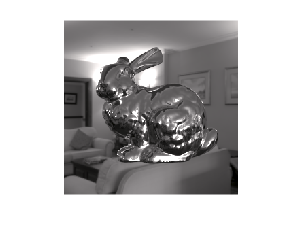

imshow(digital_rgb);

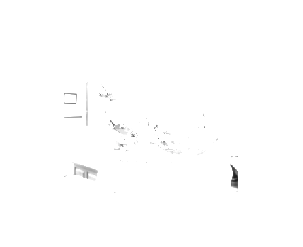

imshow(rgbImgout);